# load and plot gnss and tilt data

% chose a time when most stations are available as reference
reftime = datetime(2009,1,1);

% use m_map package (can also use mapping toolbox)
addpath m_map

%set up coordinate system
UTMproj = m_proj('UTM','long',[-155.271-1 -155.271+1],'lat',[19.391-1 19.391+1]);

%define gem12 colors to use in plots (for old matlab versions)
colors = [0	0.447000000000000	0.741000000000000
        0.850000000000000	0.325000000000000	0.0980000000000000
        0.929000000000000	0.694000000000000	0.125000000000000
        0.494000000000000	0.184000000000000	0.556000000000000
        0.466000000000000	0.674000000000000	0.188000000000000
        0.301000000000000	0.745000000000000	0.933000000000000
        0.635000000000000	0.0780000000000000	0.184000000000000
        1	0.839000000000000	0.0390000000000000
        0.396000000000000	0.509000000000000	0.992000000000000
        1	0.270000000000000	0.227000000000000
        0	0.639000000000000	0.639000000000000
        0.796000000000000	0.517000000000000	0.364000000000000];

## source model info

%HMM reservoir parameters from Anderson 2019
%HMM is relatively well constrained, and so these parameters are 
%roughly consistent with other inversions over the years
source.latlon_ref = [19.4073, -155.2784]; %reference lat-lon from Anderson 2019
[source.east_ref, source.north_ref,~] = m_ll2xy(source.latlon_ref(2),source.latlon_ref(1));
source.east = source.east_ref + 70.3;
source.north = source.north_ref + 183;
[source.lat,source.lon] = m_xy2ll(source.east,source.north);
source.V = 3.94E9;
source.aspectratio = 1.23;
source.R_hor = (source.V*3/(4*pi*source.aspectratio))^(1/3);
source.R_vert = source.aspectratio*source.R_hor;
source.Zref = 1100; %reference elevation from Anderson 2019
source.depth = 1940;
source.Z = source.Zref -source.depth;

%SCR parameters, mainly from Anderson 2020 (in turn based on previous studies)
%SCR is less well constrained, with different studies finding appriciably
%different source properties
SCR_source.V = 20E9; %reservoir volume (high uncertainty)
SCR_source.aspectratio = 1; %height/width (high uncertainty)
SCR_source.R_hor = (SCR_source.V*3/(4*pi*SCR_source.aspectratio))^(1/3);
SCR_source.R_vert = SCR_source.aspectratio*SCR_source.R_hor;
[SCR_source.east, SCR_source.north] = m_ll2xy(-155.271,19.391);
SCR_source.depth = 4000; %depth (high uncertainty)
SCR_source.Zref = 1000;%guessing this is close to the reference depth used

%south flank model sent by emily based off owens 2000
%an updated south flank motion model hasn't been made in decades,
%so this model isn't ideal but is probably the best available for now
%note that the south flank motion slowed down after 2018, though patterns
%look roughly similar
[emily_origin_east,emily_origin_north] = m_ll2xy(-155.27325676137, 19.3390574051915); 
estruct = load('kilauea_steady_state_GPS_only_90_96_PAPER.mat');


## load gnss data

This gnss data is already in a hawaii reference frame and somewhat cleaned (e.g., artifacts from instrument adjustments and etc. removed). It is HVO's daily solutions, which they seem to prefer to UNAVCO solutions, but they shouldn't be too different. HVO does have higher rate GNSS data available, but only back to around 2018. We could process our own high rate GNSS data if needed, but it might not be worth the effort.

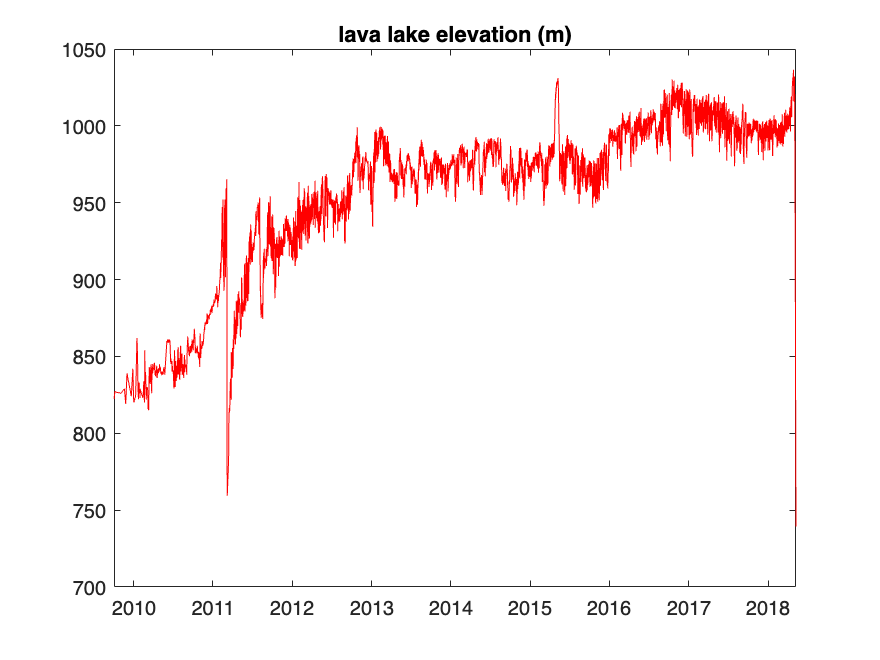

gnss = struct();
% including KOSM since it is often used as a reference station for Kilauea 
% high-rate GNSS data, due to being close enough to have similar atmospheric 
% noise, although it is still somewhat sensitive to the summit reservoirs
station = 1;
refstation = 1;
gnss(station).station="KOSM";
gnss(station).latlon=[19.3633, -155.3165, 990];
% all other stations that are nearby enough to maybe be useful
station = station+1;
gnss(station).station="BYRL";
gnss(station).latlon=[19.41196286, -155.26003039, 1099.1151671689];
station = station+1;
gnss(station).station="CNPK";
gnss(station).latlon=[19.39223856, -155.29418440, 19.39144];
station = station+1;
gnss(station).station="CRIM";
gnss(station).latlon=[19.3952924444444, -155.273765583333, 1147];
station = station+1;
gnss(station).station="HOVL";
gnss(station).latlon=[19.4042273333333, -155.279484111111, 1130.628];
station = station+1;
gnss(station).station="NPIT";
gnss(station).latlon=[19.4122783888889, -155.280998888889, 1134.355];
station = station+1;
gnss(station).station="OUTL";
gnss(station).latlon=[19.38693133, -155.28081389, 1106.186];
station = station+1;
gnss(station).station="PUHI";
gnss(station).latlon=[19.385551035, -155.251313676, 1108.7];
station = station+1;
gnss(station).station="UWEV";
gnss(station).latlon=[19.4208710459197, -155.291124126651, 1257];
% CALM and CALS might be useful, but are only available after 2018
station = station+1;
gnss(station).station="CALM";
gnss(station).latlon=[19.41018, -155.27438, 941.922];
station = station+1;
gnss(station).station="CALS";
gnss(station).latlon=[19.40676, -155.2686, 1099.44];

%convert station locations to UTM
for station = 1:length(gnss)
   gnss(station).loc = [0 0 0];
   [gnss(station).loc(1), gnss(station).loc(2)] = m_ll2xy(gnss(station).latlon(2),gnss(station).latlon(1)); 
   gnss(station).loc(3) = gnss(station).latlon(3);
end

% load gnss data
dates = datetime(2006,1,1,12,0,0):days(1):datetime(2024,11,19,12,0,0);
for station = 1:length(gnss)
    gnss(station).dat = readtimetable(fullfile(...
        'gnss_data',strcat(gnss(station).station,"_hvo_def_gps_CleanLocal.csv")),"NumHeaderLines",4);
    gnss(station).dat.Properties.VariableNames = ["Epoch","north","east","vert"];
    gnss(station).dat.Properties.DimensionNames{1} = 'Time';
    % retime to fill data gaps with NaN (so clear where they are on plots)
    % and to make all stations same size
    gnss(station).dat = retime(gnss(station).dat, dates, "fillwithmissing");
    % calculate horizontal radials relative to HMM
    unit = [gnss(station).loc(1)-source.east,gnss(station).loc(2)-source.north];
    unit = unit/sqrt(unit(1)^2 + unit(2)^2);
    gnss(station).dat.radial = gnss(station).dat.east*unit(1) + gnss(station).dat.north*unit(2);
end
figure()
colororder(colors)
for station = 2:length(gnss)
    subplot(2,1,1)
    p1 = plot(gnss(station).dat.Time,gnss(station).dat.vert); hold on
    subplot(2,1,2)
    p2 = plot(gnss(station).dat.Time,gnss(station).dat.radial); hold on
    if strcmp(gnss(station).station,'KOSM')
        p1.Color = 'k';
        p2.Color = 'k';
    elseif strcmp(gnss(station).station,'CALS') || strcmp(gnss(station).station,'CALM')
        p1.LineWidth = 2;
        p2.LineWidth = 2;
    end
end
subplot(2,1,1)
title('vert (m)')
ylim([-2,1])
legend({gnss(2:end).station})
subplot(2,1,2)
title('radial (m)')
ylim([-1,2])

## GNSS shift based on reference time

note that this is not meaningful for the later stations (CALS and CALM), so if you want to use those it  would be good to come up alternative ways to temporally reference things.

for station = 1:length(gnss) 
    if ~strcmp(gnss(station).station,'CALS') || strcmp(gnss(station).station,'CALM')
        reftimein = find(gnss(station).dat.Time>=reftime, 1);
        gnss(station).dat{:,2:5} = gnss(station).dat{:,2:5} - gnss(station).dat{reftimein,2:5};
    end
end
figure()
colororder(colors)
for station = 2:length(gnss)
    subplot(2,1,1)
    p1 = plot(gnss(station).dat.Time,gnss(station).dat.vert); hold on
    subplot(2,1,2)
    p2 = plot(gnss(station).dat.Time,gnss(station).dat.radial); hold on
    if strcmp(gnss(station).station,'KOSM')
        p1.Color = 'k';
        p2.Color = 'k';
    elseif strcmp(gnss(station).station,'CALS') || strcmp(gnss(station).station,'CALM')
        p1.LineWidth = 2;
        p2.LineWidth = 2;
    end
end
subplot(2,1,1)
title('vert (m)')
ylim([-2,1])
legend({gnss(2:end).station})
subplot(2,1,2)
title('radial (m)')
ylim([-1,2])

## GNSS fillgaps 

!!! be careful with this, since some gaps are big enough that just linearly interpolating across them is not ideal.

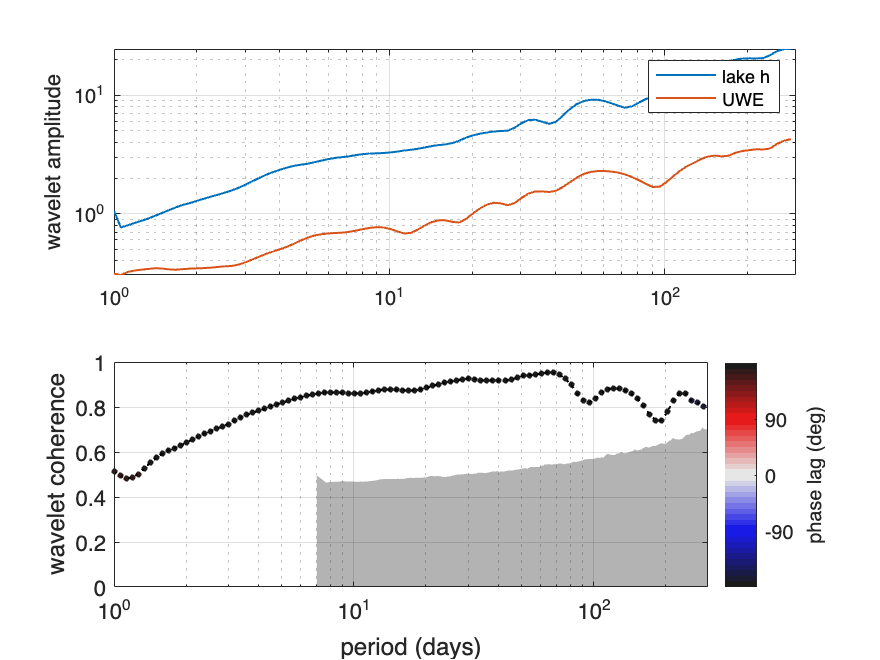

for station = 1:length(gnss)
    gnss(station).dat(:,2:5) = fillmissing(gnss(station).dat(:,2:5), 'linear', EndValues=NaN);
end
figure()
colororder(colors)
for station = 2:length(gnss)
    subplot(2,1,1)
    p1 = plot(gnss(station).dat.Time,gnss(station).dat.vert); hold on
    subplot(2,1,2)
    p2 = plot(gnss(station).dat.Time,gnss(station).dat.radial); hold on
    if strcmp(gnss(station).station,'KOSM')
        p1.Color = 'k';
        p2.Color = 'k';
    elseif strcmp(gnss(station).station,'CALS') || strcmp(gnss(station).station,'CALM')
        p1.LineWidth = 2;
        p2.LineWidth = 2;
    end
end
subplot(2,1,1)
title('vert (m)')
ylim([-2,1])
legend({gnss(2:end).station})
subplot(2,1,2)
title('radial (m)')
ylim([-1,2])

## GNSS south flank corr

south flank model sent by emily based off owens 2000, an updated south flank motion model hasn't been made in decades, so this model isn't ideal but is probably the best available for now, note that the south flank motion slowed down after 2018, though patterns look roughly similar

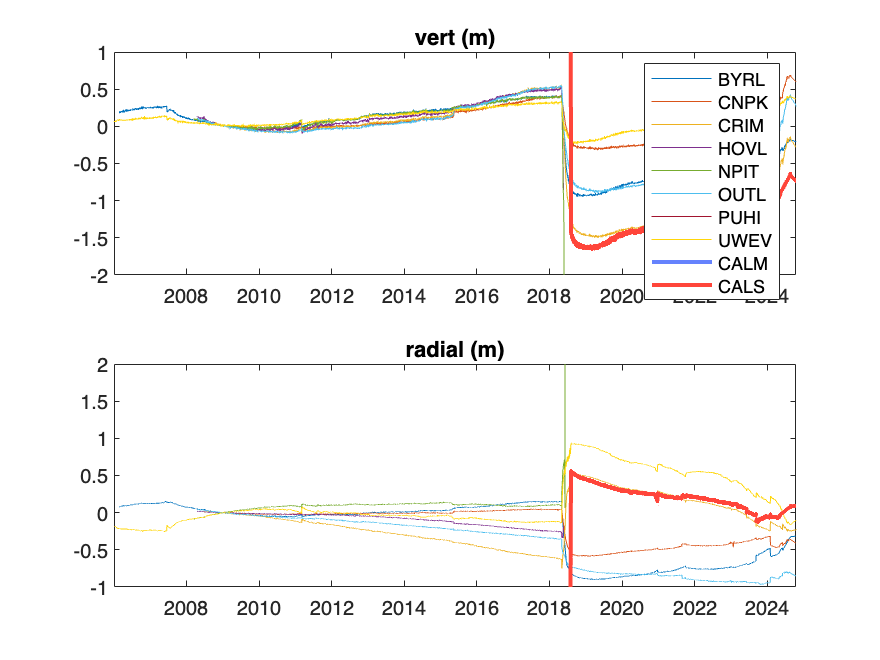

%station locations in emily's reference frame
loc_east_vec = NaN(size(gnss));
loc_north_vec = NaN(size(gnss));
for station = 1:length(gnss)
    loc_east_vec(station) = gnss(station).loc(1) - emily_origin_east;
    loc_north_vec(station) = gnss(station).loc(2) - emily_origin_north;
end
xy = [loc_east_vec;loc_north_vec;0*loc_north_vec];
% Make Green's Functions with Unit displacements 
U_dikeop = zeros(size(xy));
for i = 1:size(estruct.PMd1_op,2)
    PMd1_op = estruct.PMd1_op;   % PMd1 only has a binary bit for slip/opening component, so we need to fill in the estimated slip/opening
    PMd1_op(8,:) = 0; PMd1_op(9,:) = 0; PMd1_op(10,:) = estruct.OP(i);  % Make sure all slip/opening are set to Zero except the current component
    [U_dikeop_temp,D_dikeop] = disloc3d_cervelli(PMd1_op(:,i),xy,estruct.nu,estruct.mu);
    U_dikeop = U_dikeop + U_dikeop_temp;
end 
% Rift Strike Slip
U_dikess = zeros(size(xy));
for i = 1:size(estruct.PMd1_ss,2)
    PMd1_ss = estruct.PMd1_ss; 
    PMd1_ss(9,:) = 0; PMd1_ss(10,:); PMd1_ss(8,:) = estruct.SS(i);  % Make sure all slip/opening are set to Zero except the current component
    [U_dikess_temp,D_dikess] = disloc3d_cervelli(PMd1_ss(:,i),xy,estruct.nu,estruct.mu);
    U_dikess = U_dikess + U_dikess_temp;
end
% Decollement dip-slip Green's Function
U_decol = zeros(size(xy));
for i = 1:size(estruct.PM,2)
    PM_ds = estruct.PM; 
    PM_ds(8,:) = 0; PM_ds(10,:) = 0; PM_ds(9,:) = -estruct.DS(i);  % Make sure all slip/opening are set to Zero except the current component
    [U_decol_temp, D_decol] = disloc3d_cervelli(PM_ds(:,i),xy,estruct.nu,estruct.mu);
    U_decol = U_decol + U_decol_temp;  
end
% Add up the contributions from each component
U_flank = U_dikeop + U_dikess + U_decol;
% Add correction to data
for station = 1:length(gnss)
    gnss(station).dat.eastcorr = gnss(station).dat.east - (years(gnss(station).dat.Time - reftime))...
        *U_flank(1,station);
    gnss(station).dat.northcorr = gnss(station).dat.north - (years(gnss(station).dat.Time - reftime))...
        *U_flank(2,station);
    gnss(station).dat.vertcorr = gnss(station).dat.vert - (years(gnss(station).dat.Time - reftime))...
        *U_flank(3,station);
    % calculate horizontal radials relative to HMM
    unit = [gnss(station).loc(1)-source.east,gnss(station).loc(2)-source.north];
    unit = unit/sqrt(unit(1)^2 + unit(2)^2);
    gnss(station).dat.radialcorr = gnss(station).dat.eastcorr*unit(1) + gnss(station).dat.northcorr*unit(2);
end
figure()
colororder(colors)
for station = 2:length(gnss)
    subplot(2,1,1)
    p1 = plot(gnss(station).dat.Time,gnss(station).dat.vertcorr); hold on
    subplot(2,1,2)
    p2 = plot(gnss(station).dat.Time,gnss(station).dat.radialcorr); hold on
    if strcmp(gnss(station).station,'KOSM')
        p1.Color = 'k';
        p2.Color = 'k';
    elseif strcmp(gnss(station).station,'CALS') || strcmp(gnss(station).station,'CALM')
        p1.LineWidth = 2;
        p2.LineWidth = 2;
    end
end
subplot(2,1,1)
title('vert (m)')
ylim([-2,1])
legend({gnss(2:end).station})
subplot(2,1,2)
title('radial (m)')
ylim([-1,2])

## GNSS reference to KOSM

!!! KOSM is often used as a reference station for Kilauea high-rate GNSS data, due to being close enough to have similar atmospheric noise, although it is still somewhat sensitive to the summit reservoirs.

Since we aren't using high-rate GNSS data for now, and since KOSM is also senstive to SW rift intrusions and has some data gaps, it should probably not be used as a reference for now.

% for station = 1:length(gnss)
%     sin = ismember(gnss(station).dat.Time, gnss(refstation).dat.Time);
%     rin = ismember(gnss(refstation).dat.Time, gnss(station).dat.Time);
%     gnss(station).dat{sin,2:5} = gnss(station).dat{sin,2:5} - gnss(refstation).dat{rin,2:5};
% end
% figure()
% colororder(colors)
% for station = 2:length(gnss)
%     subplot(2,1,1)
%     p1 = plot(gnss(station).dat.Time,gnss(station).dat.vert); hold on
%     subplot(2,1,2)
%     p2 = plot(gnss(station).dat.Time,gnss(station).dat.radial); hold on
%     if strcmp(gnss(station).station,'KOSM')
%         p1.Color = 'k';
%         p2.Color = 'k';
%     elseif strcmp(gnss(station).station,'CALS') || strcmp(gnss(station).station,'CALM')
%         p1.LineWidth = 2;
%         p2.LineWidth = 2;
%     end
% end
% subplot(2,1,1)
% title('vert (m)')
% ylim([-2,1])
% legend({gnss(2:end).station})
% subplot(2,1,2)
% title('radial (m)')
% ylim([-1,2])

## plot gnss HMM + SCR greens functions

plotting the green's functions can help see which stations (and components of each station) are more sensitive to each of the two summit reservoirs.

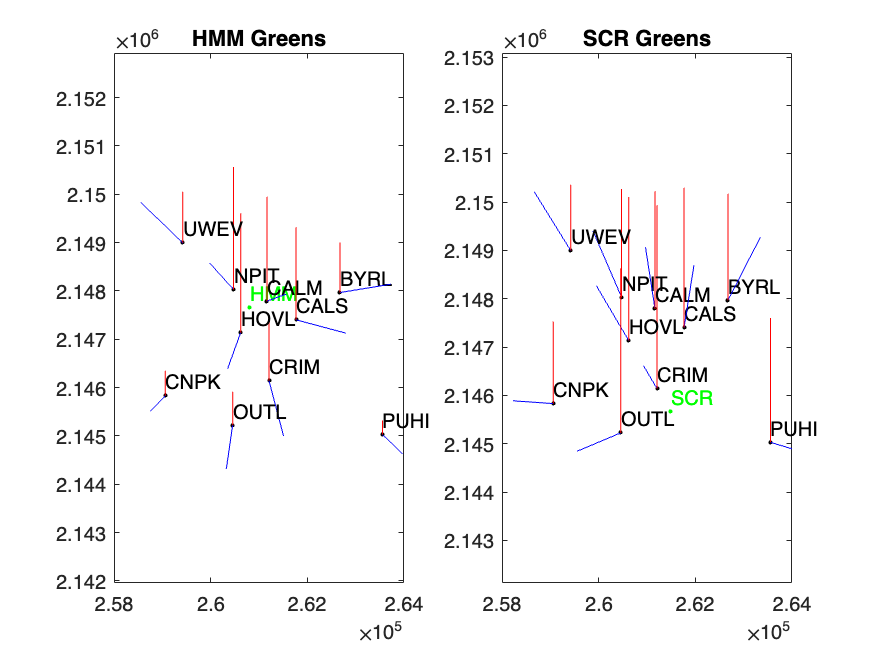

strength_type = 'pressure';
strength_scale = 1E6;
nu = 0.25; %poisson ratio
mu = 3.08E9; %shear modulus

m = [source.R_vert;%       vertical semi-diameter (length)
    source.R_hor;%       horizontal semi-diameters (length)
    90;%       dip (degrees)
    0;%       strike (degrees)
    source.east;%       X1 position (length)
    source.north;%       X2 position (length)
    -source.depth;%       X3 position (length)
    -strength_scale];%       strength, pressure change (force/length^2) or volume change (m^3)

SCR_m = [SCR_source.R_vert;%       vertical semi-diameter (length)
    SCR_source.R_hor;%       horizontal semi-diameters (length)
    90;%       dip (degrees)
    0;%       strike (degrees)
    SCR_source.east;%       X1 position (length)
    SCR_source.north;%       X2 position (length)
    -SCR_source.depth;%       X3 position (length)
    -strength_scale];%       strength, pressure change (force/length^2) or volume change (m^3)

for station = 1:length(gnss)
    xyz_temp = [gnss(station).loc(1); gnss(station).loc(2); 0];
    m_temp = m;
    m_temp(7) = -source.depth + (gnss(station).latlon(3)-source.Zref);
    gnss(station).u_pred = spheroid(m_temp,xyz_temp,nu,mu,strength_type);
    m_temp = SCR_m;
    m_temp(7) = -SCR_source.depth + (gnss(station).latlon(3)-SCR_source.Zref);
    gnss(station).SCR_u_pred = spheroid(m_temp,xyz_temp,nu,mu,strength_type);
end

figure()
scale = 50000;
subplot(1,2,1)
plot(source.east,source.north,'g.'), hold on
text(source.east,source.north+300,'HMM',Color='g')
xlim([2.58E5,2.64E5]),ylim([2.144E6,2.15E6])
axis equal
title('HMM Greens')
subplot(1,2,2)
plot(SCR_source.east,SCR_source.north,'g.'), hold on
text(SCR_source.east,SCR_source.north+300,'SCR',Color='g')
xlim([2.58E5,2.64E5]),ylim([2.144E6,2.15E6])
axis equal
title('SCR Greens')
for station = 2:length(gnss)
    subplot(1,2,1)
    plot(gnss(station).loc(1),gnss(station).loc(2),'k.')
    text(gnss(station).loc(1),gnss(station).loc(2)+300,gnss(station).station)
    plot([gnss(station).loc(1),gnss(station).loc(1)+gnss(station).u_pred(1)*scale],...
         [gnss(station).loc(2),gnss(station).loc(2)+gnss(station).u_pred(2)*scale],'b-')
    plot([gnss(station).loc(1),gnss(station).loc(1)],...
         [gnss(station).loc(2),gnss(station).loc(2)+gnss(station).u_pred(3)*scale],'r-')
    subplot(1,2,2)
    plot(gnss(station).loc(1),gnss(station).loc(2),'k.')
    text(gnss(station).loc(1),gnss(station).loc(2)+300,gnss(station).station)
    plot([gnss(station).loc(1),gnss(station).loc(1)+gnss(station).SCR_u_pred(1)*scale],...
         [gnss(station).loc(2),gnss(station).loc(2)+gnss(station).SCR_u_pred(2)*scale],'b-')
    plot([gnss(station).loc(1),gnss(station).loc(1)],...
         [gnss(station).loc(2),gnss(station).loc(2)+gnss(station).SCR_u_pred(3)*scale],'r-')
end

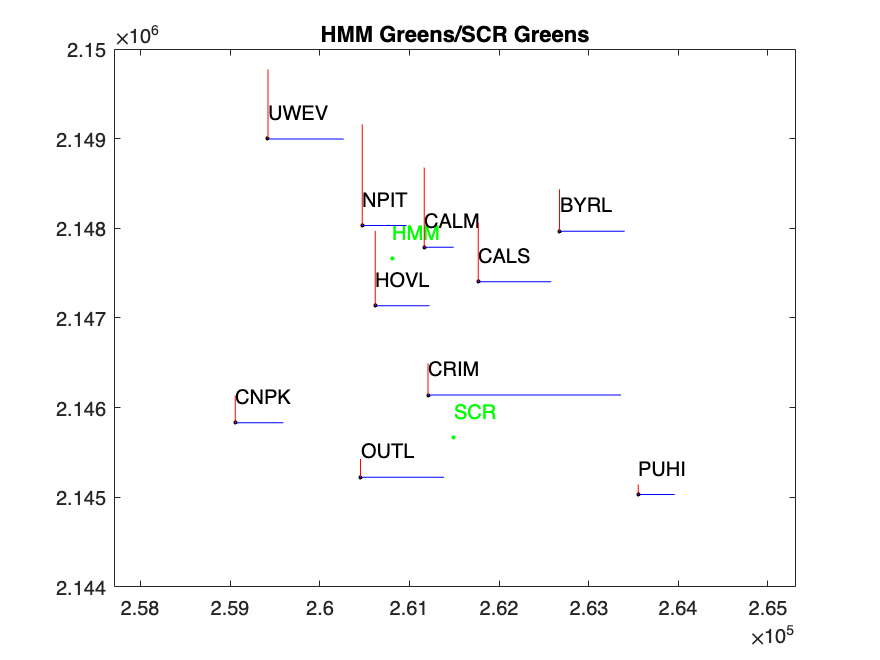

% plotting a ratio between the greens functions helps give 
% a sense of what stations are more/less sensitive to the SCR
% (the scale is arbitrary since it's all relative)
% so we can see that the vertical components of 
% CNPK, CRIM, OUTL, and PUHI are all relatively strongly impacted 
% by the SCR, and the horizontal components of CALM, CNPK, HOVL, NPIT, and
% PUHI are relatively strongly impacted by the SCR
figure()
scale = 1000;
plot(source.east,source.north,'g.'), hold on
text(source.east,source.north+300,'HMM',Color='g')
plot(SCR_source.east,SCR_source.north,'g.'), hold on
text(SCR_source.east,SCR_source.north+300,'SCR',Color='g')
xlim([2.58E5,2.64E5]),ylim([2.144E6,2.15E6])
axis equal
title('HMM Greens/SCR Greens')
for station = 2:length(gnss)
    plot(gnss(station).loc(1),gnss(station).loc(2),'k.')
    text(gnss(station).loc(1),gnss(station).loc(2)+300,gnss(station).station)
    plot([gnss(station).loc(1),gnss(station).loc(1)+...
        (sqrt(gnss(station).u_pred(1)^2+gnss(station).u_pred(2)^2)/...
         sqrt(gnss(station).SCR_u_pred(1)^2+gnss(station).SCR_u_pred(2)^2))*scale],...
         [gnss(station).loc(2),gnss(station).loc(2)],'b-')
    plot([gnss(station).loc(1),gnss(station).loc(1)],...
         [gnss(station).loc(2),gnss(station).loc(2)+...
         (gnss(station).u_pred(3)/gnss(station).SCR_u_pred(3))*scale],'r-')
end

%using line lengths across HMM is one possible way to minimize SCR
%influence. We can check a couple of these that seem promising:
UWEV_BYRL = struct();
UWEV_in = 9;
BYRL_in = 2;
UWEV_BYRL.locdiff = gnss(UWEV_in).loc(1:2) - gnss(BYRL_in).loc(1:2);
UWEV_BYRL.locdiffunit = UWEV_BYRL.locdiff/sqrt(sum(UWEV_BYRL.locdiff.^2));
UWEV_BYRL.linelen = gnss(UWEV_in).u_pred(1:2)'*UWEV_BYRL.locdiffunit' - ...
                    gnss(BYRL_in).u_pred(1:2)'*UWEV_BYRL.locdiffunit';
UWEV_BYRL.SCR_linelen = gnss(UWEV_in).SCR_u_pred(1:2)'*UWEV_BYRL.locdiffunit' - ...
                        gnss(BYRL_in).SCR_u_pred(1:2)'*UWEV_BYRL.locdiffunit';
UWEV_BYRL_linelen_and_SCRlinelen_and_ratio = ...
    [UWEV_BYRL.linelen, UWEV_BYRL.SCR_linelen, UWEV_BYRL.linelen/UWEV_BYRL.SCR_linelen]

UWEV_BYRL_linelen_and_SCRlinelen_and_ratio =     0.0407    0.0266    1.5288


UWEV_CRIM = struct();
UWEV_in = 9;
CRIM_in = 4;
UWEV_CRIM.locdiff = gnss(UWEV_in).loc(1:2) - gnss(CRIM_in).loc(1:2);
UWEV_CRIM.locdiffunit = UWEV_CRIM.locdiff/sqrt(sum(UWEV_CRIM.locdiff.^2));
UWEV_CRIM.linelen = gnss(UWEV_in).u_pred(1:2)'*UWEV_CRIM.locdiffunit' - ...
                    gnss(CRIM_in).u_pred(1:2)'*UWEV_CRIM.locdiffunit';
UWEV_CRIM.SCR_linelen = gnss(UWEV_in).SCR_u_pred(1:2)'*UWEV_CRIM.locdiffunit' - ...
                        gnss(CRIM_in).SCR_u_pred(1:2)'*UWEV_CRIM.locdiffunit';
UWEV_CRIM_linelen_and_SCRlinelen_and_ratio = ...
    [UWEV_CRIM.linelen, UWEV_CRIM.SCR_linelen, UWEV_CRIM.linelen/UWEV_CRIM.SCR_linelen]

UWEV_CRIM_linelen_and_SCRlinelen_and_ratio =     0.0460    0.0176    2.6098


## load tilt

Tilt is much messier. The tilt data on HVO's valve server apparently already has some instrument issues approximately corrected for, but there are still many offsets. Some of these might represent real EQs or etc., but there may also still be some instrument issues. We do have the tilt log files, which would be good to look through at some point. Also, there are known issues with some of the instruments (for instance, according to Kyle IKI has strong temperature-driven diurnal signals, UWE might also have some temperature sensitivity, and SMC seems to sometimes point in the wrong direction). UWE is probably the safest station to use, but others that might also be helpful are included. For now, this script just grabs the raw tilt data and does very basic cleaning.

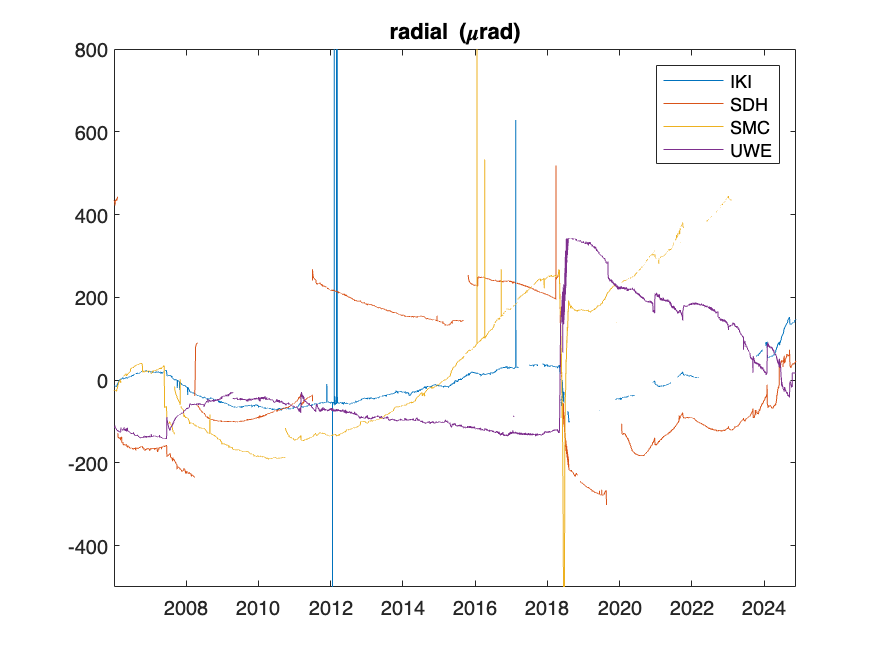

tilt = struct();
station = 1;
tilt(station).station="IKI";
tilt(station).latlon=[19.4191, -155.2458, 1167];
station = station+1;
tilt(station).station="SDH";
tilt(station).latlon=[19.390003, -155.293995, 1131];
station = station+1;
tilt(station).station="SMC";
tilt(station).latlon=[19.40612, -155.25736, 1097];
station = station+1;
tilt(station).station="UWE";
tilt(station).latlon=[19.4209, -155.2909, 1214];

%convert station locations to UTM
for station = 1:length(tilt)
   tilt(station).loc = [0 0 0];
   [tilt(station).loc(1), tilt(station).loc(2)] = m_ll2xy(tilt(station).latlon(2),tilt(station).latlon(1)); 
   tilt(station).loc(3) = tilt(station).latlon(3);
end

% load tilt data
dates = datetime(2006,1,1,12,0,0):hours(1):datetime(2024,11,19,12,0,0);
for station = 1:length(tilt)
    tilt(station).dat = readtimetable(fullfile(...
        'tilt_data',strcat(tilt(station).station,"_hvo_def_tilt_RawData.csv")),"NumHeaderLines",4);
    tilt(station).dat.Properties.VariableNames = ["Epoch","north","east"];
    tilt(station).dat.Properties.DimensionNames{1} = 'Time';
    % retime to fill data gaps with NaN (so clear where they are on plots)
    % and to make all stations same size
    tilt(station).dat = retime(tilt(station).dat, dates, "fillwithmissing");
    % calculate horizontal radials relative to HMM 
    unit = [tilt(station).loc(1)-source.east,tilt(station).loc(2)-source.north];
    unit = unit/sqrt(unit(1)^2 + unit(2)^2);
    tilt(station).dat.radial = tilt(station).dat.east*unit(1) + tilt(station).dat.north*unit(2);
end
figure()
colororder(colors)
for station = 1:length(tilt)
    p1 = plot(tilt(station).dat.Time,tilt(station).dat.radial); hold on
end
title('radial (\murad)')
ylim([-500,800])
legend({tilt(1:end).station})

## tilt shift based on reference time

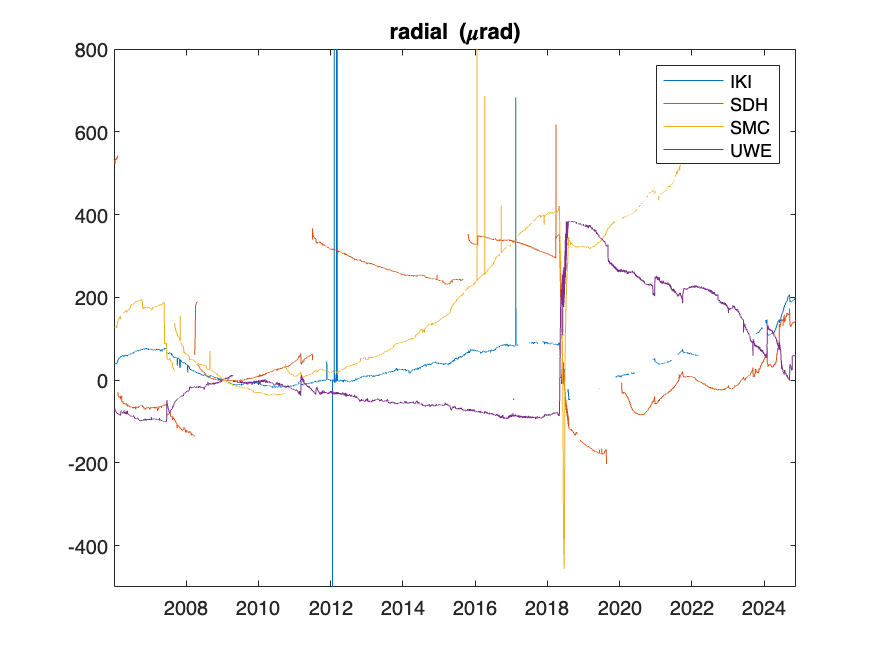

for station = 1:length(tilt) 
    reftimein = find(tilt(station).dat.Time>=reftime, 1);
    tilt(station).dat{:,2:4} = tilt(station).dat{:,2:4} - tilt(station).dat{reftimein,2:4};
end
figure()
for station = 1:length(tilt)
    p1 = plot(tilt(station).dat.Time,tilt(station).dat.radial); hold on
end
title('radial (\murad)')
ylim([-500,800])
legend({tilt(1:end).station})

## tilt remove outliers

!!! this is somewhat arbitrary, so might be worth more careful tinkering at some point

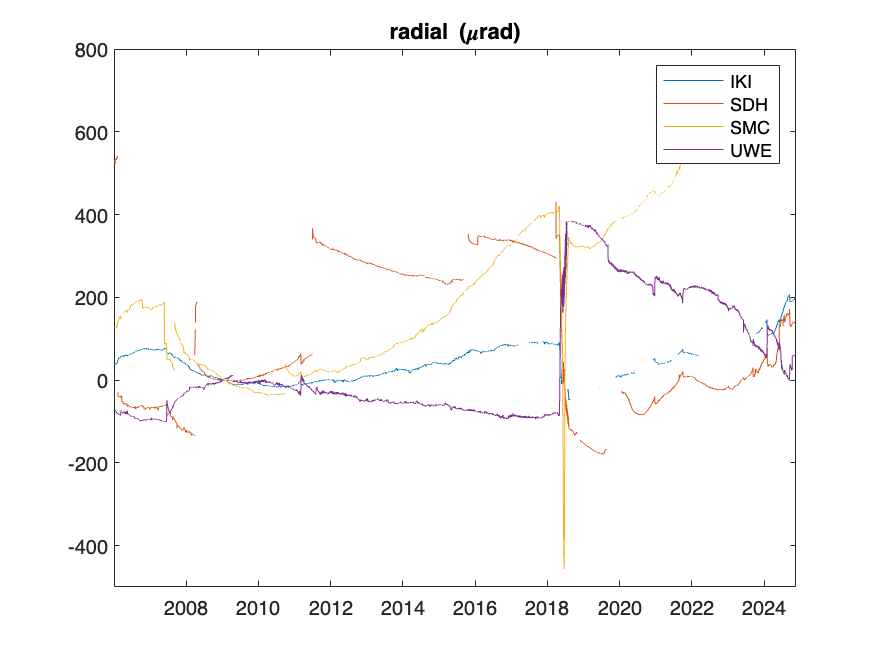

window = days(15); %chosen to visibly remove some obvious outliers
for station = 1:length(tilt)
    tilt(station).dat(:,2:4) = filloutliers(tilt(station).dat(:,2:4), NaN, 'movmed', window);
end
figure()
for station = 1:length(tilt)
    p1 = plot(tilt(station).dat.Time,tilt(station).dat.radial); hold on
end
title('radial (\murad)')
ylim([-500,800])
legend({tilt(1:end).station})

## tilt fillgaps 

!!! be careful with this, since some gaps are large enough that just linearly interpolating across them is not ideal

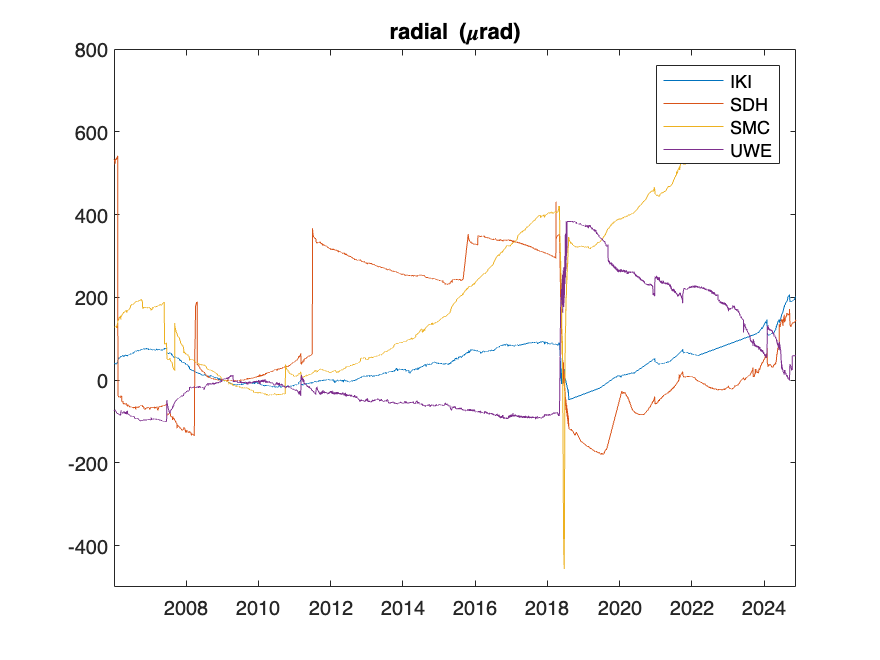

for station = 1:length(tilt)
    tilt(station).dat(:,2:4) = fillmissing(tilt(station).dat(:,2:4), 'linear', EndValues=NaN);
end
figure()
for station = 1:length(tilt)
    p1 = plot(tilt(station).dat.Time,tilt(station).dat.radial); hold on
end
title('radial (\murad)')
ylim([-500,800])
legend({tilt(1:end).station})

## tilt south flank correction

south flank model sent by emily based off owens 2000, an updated south flank motion model hasn't been made in decades, so this model isn't ideal but is probably the best available for now, note that the south flank motion slowed down after 2018, though patterns look roughly similar

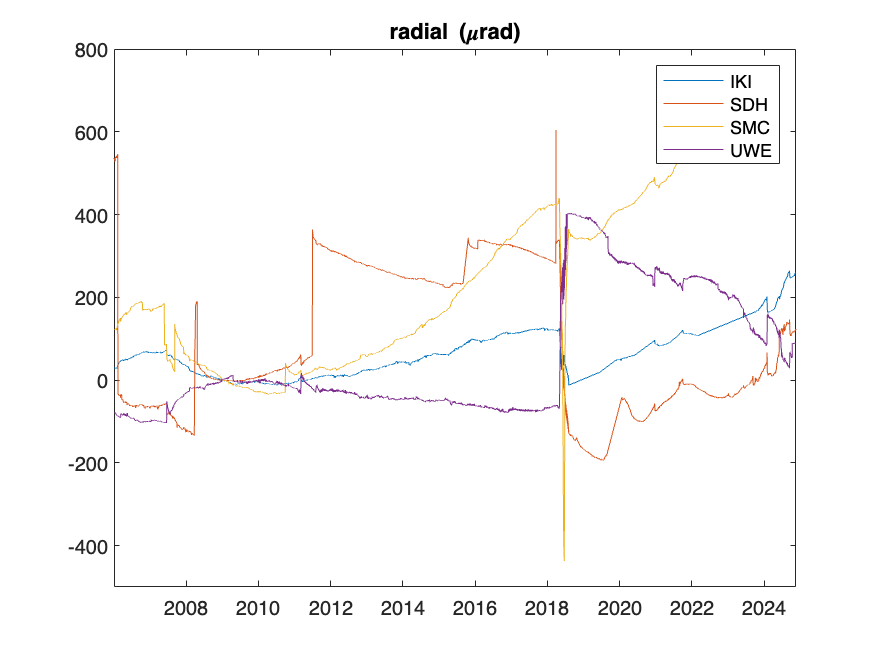

loc_east_vec = NaN(size(tilt));
loc_north_vec = NaN(size(tilt));
for station = 1:length(tilt)
    loc_east_vec(station) = tilt(station).loc(1) - emily_origin_east;
    loc_north_vec(station) = tilt(station).loc(2) - emily_origin_north;
end
dx = 1;
xy_tilt = [loc_east_vec;loc_north_vec;0*loc_north_vec];
xy_tilt_xp = [loc_east_vec+dx;loc_north_vec;0*loc_north_vec];
xy_tilt_yp = [loc_east_vec;loc_north_vec+dx;0*loc_north_vec];
% Make Green's Functions with Unit displacements
U_dikeop_tilt = zeros(size(xy_tilt));
U_dikeop_tilt_xp = zeros(size(xy_tilt));
U_dikeop_tilt_yp = zeros(size(xy_tilt));
for i = 1:size(estruct.PMd1_op,2)
    PMd1_op = estruct.PMd1_op;   % PMd1 only has a binary bit for slip/opening component, so we need to fill in the estimated slip/opening
    PMd1_op(8,:) = 0; PMd1_op(9,:) = 0; PMd1_op(10,:) = estruct.OP(i);  % Make sure all slip/opening are set to Zero except the current component
    [U_dikeop_temp,D_dikeop] = disloc3d_cervelli(PMd1_op(:,i),xy_tilt,estruct.nu,estruct.mu);
    U_dikeop_tilt = U_dikeop_tilt + U_dikeop_temp;
    [U_dikeop_temp_xp,D_dikeop_xp] = disloc3d_cervelli(PMd1_op(:,i),xy_tilt_xp,estruct.nu,estruct.mu);
    U_dikeop_tilt_xp = U_dikeop_tilt_xp + U_dikeop_temp_xp;
    [U_dikeop_temp_yp,D_dikeop_yp] = disloc3d_cervelli(PMd1_op(:,i),xy_tilt_yp,estruct.nu,estruct.mu);
    U_dikeop_tilt_yp = U_dikeop_tilt_yp + U_dikeop_temp_yp;
end 
% Rift Strike Slip  (In this case, this could be combined with 
U_dikess_tilt = zeros(size(xy_tilt));
U_dikess_tilt_xp = zeros(size(xy_tilt));
U_dikess_tilt_yp = zeros(size(xy_tilt));
for i = 1:size(estruct.PMd1_ss,2)
    PMd1_ss = estruct.PMd1_ss; 
    PMd1_ss(9,:) = 0; PMd1_ss(10,:); PMd1_ss(8,:) = estruct.SS(i);  % Make sure all slip/opening are set to Zero except the current component
    [U_dikess_temp,D_dikess] = disloc3d_cervelli(PMd1_ss(:,i),xy_tilt,estruct.nu,estruct.mu);
    U_dikess_tilt = U_dikess_tilt + U_dikess_temp;
    [U_dikess_temp_xp,D_dikess_xp] = disloc3d_cervelli(PMd1_ss(:,i),xy_tilt_xp,estruct.nu,estruct.mu);
    U_dikess_tilt_xp = U_dikess_tilt_xp + U_dikess_temp_xp;
    [U_dikess_temp_yp,D_dikess_yp] = disloc3d_cervelli(PMd1_ss(:,i),xy_tilt_yp,estruct.nu,estruct.mu);
    U_dikess_tilt_yp = U_dikess_tilt_yp + U_dikess_temp_yp;
end
% Decollement dip-slip Green's Function
U_decol_tilt = zeros(size(xy_tilt));
U_decol_tilt_xp = zeros(size(xy_tilt));
U_decol_tilt_yp = zeros(size(xy_tilt));
for i = 1:size(estruct.PM,2)
    PM_ds = estruct.PM; 
    PM_ds(8,:) = 0; PM_ds(10,:) = 0; PM_ds(9,:) = -estruct.DS(i);  % Make sure all slip/opening are set to Zero except the current component
    [U_decol_temp, D_decol] = disloc3d_cervelli(PM_ds(:,i),xy_tilt,estruct.nu,estruct.mu);
    U_decol_tilt = U_decol_tilt + U_decol_temp;
    [U_decol_temp_xp,D_decol_xp] = disloc3d_cervelli(PM_ds(:,i),xy_tilt_xp,estruct.nu,estruct.mu);
    U_decol_tilt_xp = U_decol_tilt_xp + U_decol_temp_xp;
    [U_decol_temp_yp,D_decol_yp] = disloc3d_cervelli(PM_ds(:,i),xy_tilt_yp,estruct.nu,estruct.mu);
    U_decol_tilt_yp = U_decol_tilt_yp + U_decol_temp_yp;  
end
% Add up the contributions from each component
U_flank_tilt = U_dikeop_tilt + U_dikess_tilt + U_decol_tilt;
U_flank_tilt_xp = U_dikeop_tilt_xp + U_dikess_tilt_xp + U_decol_tilt_xp;
U_flank_tilt_yp = U_dikeop_tilt_yp + U_dikess_tilt_yp + U_decol_tilt_yp;
tilt_flank_east = -atan((U_flank_tilt_xp(3,:)-U_flank_tilt(3,:))/dx)*10^6; %check signs here....
tilt_flank_north = -atan((U_flank_tilt_yp(3,:)-U_flank_tilt(3,:))/dx)*10^6;
tilt_flank = [tilt_flank_east;tilt_flank_north];
% Add correction to data
for station = 1:length(tilt)
    tilt(station).dat.eastcorr = tilt(station).dat.east - (years(tilt(station).dat.Time - reftime))...
        *tilt_flank(1,station);
    tilt(station).dat.northcorr = tilt(station).dat.north - (years(tilt(station).dat.Time - reftime))...
        *tilt_flank(2,station);
    % calculate horizontal radials relative to HMM 
    unit = [tilt(station).loc(1)-source.east,tilt(station).loc(2)-source.north];
    unit = unit/sqrt(unit(1)^2 + unit(2)^2);
    tilt(station).dat.radialcorr = tilt(station).dat.eastcorr*unit(1) + tilt(station).dat.northcorr*unit(2);
end
figure()
for station = 1:length(tilt)
    p1 = plot(tilt(station).dat.Time,tilt(station).dat.radialcorr); hold on
end
title('radial (\murad)')
ylim([-500,800])
legend({tilt(1:end).station})

## **Load lava lake data**

note that this datastructure also includes uncertainty and a numerical indicator of the type of measurement being made

lakeh = readtable(fullfile('lavalake','ContinuousLavaLakeElevation.txt'),...
    'ReadVariableNames',false,'HeaderLines',2,'DatetimeType','text');
lakeh.Properties.VariableNames{'Var1'} = 'datestr';
lakeh.Properties.VariableNames{'Var2'} = 'h';
lakeh.Properties.VariableNames{'Var3'} = 'err';
lakeh.Properties.VariableNames{'Var4'} = 'type';
% different measurement types were saved with different date formats, 
% so converting them to times separately avoids issues
lakeh.date = NaT(height(lakeh),1); 
lakeh.date(lakeh.type == 1) = datetime(lakeh.datestr(lakeh.type == 1));
lakeh.date(lakeh.type == 2) = datetime(lakeh.datestr(lakeh.type == 2));
lakeh.date(lakeh.type == 3) = datetime(lakeh.datestr(lakeh.type == 3));
lakeh.date(lakeh.type == 4) = datetime(lakeh.datestr(lakeh.type == 4));
lakeh.date(lakeh.type == 5) = datetime(lakeh.datestr(lakeh.type == 5));
lakeh = removevars(lakeh,{'err','type','datestr'});
lakeh = lakeh(~isnan(lakeh.h),:);
lakeh = sortrows(lakeh,'date');
lakeh = lakeh(diff(lakeh.date)~=seconds(0),:); %remove duplicate times
lakeh = table2timetable(lakeh);
lakeh.date = lakeh.date+hours(10); % convert from HST to UTC
dates = datetime(2009,10,1,12,0,0):hours(1):datetime(2018,8,1,12,0,0);
% retime to fill data gaps with NaN (so clear where they are on plots)
% and to make all stations same size
lakeh = retime(lakeh, dates, "linear", EndValues=NaN);

figure()
plot(lakeh.date,lakeh.h,'r')
title('lava lake elevation (m)')

## plot wavelet coherence

this section gives an example of some wavelet coherence plots between UWE tilt and lake elevation

wcoh_table = timetable(lakeh.date,lakeh.h,'VariableNames',{'h'});
ts = days(1/24);
wcoh_table = retime(wcoh_table,'regular','linear','TimeStep',ts);

UWEin = find(strcmp([tilt.station],"UWE"));
UWE_resample = smoothdata(tilt(UWEin).dat,'movmean',ts);
UWE_resample = retime(UWE_resample,wcoh_table.Time,'linear');

UWEVin = find(strcmp([gnss.station],"UWEV"));
UWEV_resample = smoothdata(gnss(UWEVin).dat,'movmean',ts);
UWEV_resample = retime(UWEV_resample,wcoh_table.Time,'linear');

wcoh_table.UWEradial = UWE_resample.radial;
wcoh_table.UWEVradial = UWEV_resample.radial;
wcoh_table.UWEVvert = UWEV_resample.vert;

%specify a geodetic signal to compare to lake
DeformationOut = wcoh_table.UWEVvert;

% uncomment this block if you want to test with simple sinusoids
% wcoh_table.h = 0*wcoh_table.h+sin(days(wcoh_table.Time-datetime(2008,1,1))/20);
% wcoh_table.UWEradial = 0*wcoh_table.h+sin((days(wcoh_table.Time-datetime(2008,1,1)) - 8)/20);
% figure()
% plot(wcoh_table.Time, wcoh_table.h, wcoh_table.Time, wcoh_table.UWEradial)
% legend({'h','uwe'})

% uncomment this code block to skip 2011 time segment where lake drained
% (or modify to mask other time segments)
% note that this can introduce some artifacts though
% skipreg1 = datetime(2011,2,16);
% skipreg2 = datetime(2011,12,1);
% wcoh_table = wcoh_table(wcoh_table.Time<skipreg1 | wcoh_table.Time>skipreg2,:);
% skipreg = days([skipreg1,skipreg2] - wcoh_table.Time(1));
% wcoh_table = retime(wcoh_table,'regular','linear','TimeStep',ts);

PeriodLimits = [days(1),days(300)];
VoicesPerOctave = 12;
NumScalesToSmooth = 5;
PhaseDisplayThreshold = 0.5;

fig = figure();
xticklist = days(datetime((2010:2018),ones(1,9),ones(1,9)) - wcoh_table.Time(1));
xticklabellist = num2str((2010:2018)');
subplot(2,1,1)
% the _josh version allows masks and improves quiver plots
wcoherence_josh(wcoh_table.h,DeformationOut,ts,'PeriodLimits',PeriodLimits,...
    'VoicesPerOctave',VoicesPerOctave,'NumScalesToSmooth',NumScalesToSmooth,...
    'PhaseDisplayThreshold',PhaseDisplayThreshold);%,'skipreg',skipreg); %include skipreg to mask time segments
% rectangle('Position',[days(skipreg1 - wcoh_table.Time(1)),log2(days(PeriodLimits(1))),...
%     days(skipreg2 - skipreg1), log2(days(PeriodLimits(2))) - log2(days(PeriodLimits(1)))],...
%     'EdgeColor','none','FaceColor','w');
xticks(xticklist);
xticklabels(xticklabellist)
grid on
xline(days(datetime(2008,3,19) - wcoh_table.Time(1)),'k','LineWidth',1)%,{'Crater'},'LabelVerticalAlignment','bottom')
xline(days(datetime(2010,2,1) - wcoh_table.Time(1)),'k:','LineWidth',1)%,{'SSE'},'LabelVerticalAlignment','bottom')
xline(days(datetime(2012,5,25) - wcoh_table.Time(1)),'k:','LineWidth',1)%,{'SSE'},'LabelVerticalAlignment','bottom')
xline(days(datetime(2015,10,15) - wcoh_table.Time(1)),'k:','LineWidth',1)%,{'SSE'},'LabelVerticalAlignment','bottom')
xline(days(datetime(2011,3,5) - wcoh_table.Time(1)),'k-','LineWidth',1)%,{'ERZ'},'LabelVerticalAlignment','bottom')
xline(days(datetime(2011,8,3) - wcoh_table.Time(1)),'k-','LineWidth',1)%,{'ERZ'},'LabelVerticalAlignment','bottom')
xline(days(datetime(2011,9,21) - wcoh_table.Time(1)),'k-','LineWidth',1)%,{'ERZ'},'LabelVerticalAlignment','bottom')
xline(days(datetime(2014,6,27) - wcoh_table.Time(1)),'k-','LineWidth',1)%,{'ERZ'},'LabelVerticalAlignment','bottom')
xline(days(datetime(2016,5,24) - wcoh_table.Time(1)),'k-','LineWidth',1)%,{'ERZ'},'LabelVerticalAlignment','bottom')
xline(days(datetime(2018,4,30) - wcoh_table.Time(1)),'k-','LineWidth',1)%,{'ERZ'},'LabelVerticalAlignment','bottom')
xline(days(datetime(2012,10,26) - wcoh_table.Time(1)),'k--','LineWidth',1)%,{'Int'},'LabelVerticalAlignment','bottom')
xline(days(datetime(2014,5,10) - wcoh_table.Time(1)),'k--','LineWidth',1)%,{'Int'},'LabelVerticalAlignment','bottom')
xline(days(datetime(2015,5,9) - wcoh_table.Time(1)),'k--','LineWidth',1)%,{'Int'},'LabelVerticalAlignment','bottom')
ax2 = subplot(2,1,2);
[wcoh, wcs, period, coi] = wcoherence_josh(wcoh_table.h,DeformationOut,ts,'PeriodLimits',PeriodLimits,...
    'VoicesPerOctave',VoicesPerOctave,'NumScalesToSmooth',NumScalesToSmooth,...
    'PhaseDisplayThreshold',PhaseDisplayThreshold);%,'skipreg',skipreg); %include skipreg to mask time segments
p = pcolor(days(wcoh_table.Time-wcoh_table.Time(1)),days(period),wrapToPi(angle(wcs)));hold on
plot(days(wcoh_table.Time-wcoh_table.Time(1)),days(coi),'--w')
p.EdgeColor = 'none';
cmapr = [linspace(0.2,0.2,10),linspace(0.2,0.9,10),linspace(0.9,0.9,10),linspace(0.9,0.2,10)]';
cmapg = [linspace(0.2,0.2,10),linspace(0.2,0.9,10),linspace(0.9,0.2,10),linspace(0.2,0.2,10)]';
cmapb = [linspace(0.2,0.9,10),linspace(0.9,0.9,10),linspace(0.9,0.2,10),linspace(0.2,0.2,10)]';
cmap = [cmapr,cmapg,cmapb];
colormap(ax2,cmap)
set(gca,'YScale','log')
yticks([1,2,4,8,16,32,64,128,256,512])
clim([-pi,pi])
% rectangle('Position',[days(skipreg1 - wcoh_table.Time(1)),days(PeriodLimits(1)),...
%     days(skipreg2 - skipreg1), days(PeriodLimits(2)) - days(PeriodLimits(1))],...
%     'EdgeColor','none','FaceColor','w');
xticks(xticklist);
cbar = colorbar;
ylabel(cbar,'phase (rad)')
xticklabels(xticklabellist)
ylabel('Period (days)')
grid on
ax2.Layer = 'top';
box on
disp('positive phase (red or up arrows) means tilt is ahead of lake')

positive phase (red or up arrows) means tilt is ahead of lake


positive phase (red or up arrows) means tilt is ahead of lake


## plot wavelet coherence spectra

this section gives an example of some wavelet coherence spectra plots between UWE tilt and lake elevation

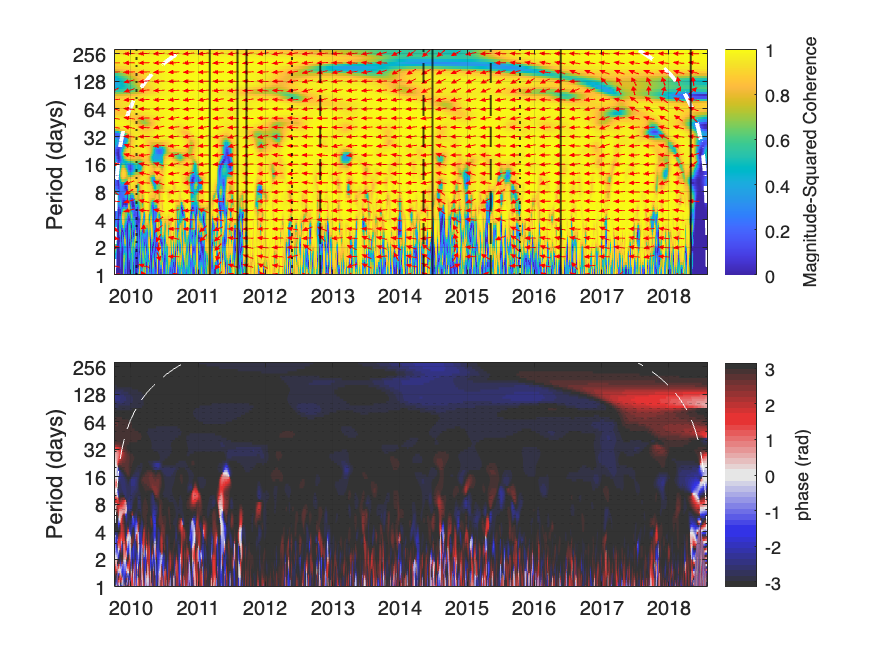

figure()
PeriodLimits = [days(1),days(300)];
VoicesPerOctave = 12;
NumScalesToSmooth = 5;

ax1 = subplot(2,1,1);
hold on
grid on
box on
xlim(days(PeriodLimits))
xticks(10.^(0:3))
ylabel('wavelet amplitude')

[wt,period,coi] = cwt(wcoh_table.h,'amor',ts,'PeriodLimits',PeriodLimits,...
    'VoicesPerOctave',VoicesPerOctave,'ExtendSignal',false);
[wt2,~,~] = cwt(DeformationOut,'amor',ts,'PeriodLimits',PeriodLimits,...
    'VoicesPerOctave',VoicesPerOctave,'ExtendSignal',false);
mask = ones(size(wt));
for jj = 1:length(coi)
    mask(period>coi(jj),jj) = 0;
end
data = sum(abs(wt).*mask,2)./sum(mask,2);
data2 = sum(abs(wt2).*mask,2)./sum(mask,2);
plot(ax1,days(period),data,'-','LineWidth',1.0);
plot(ax1,days(period),data2,'-','LineWidth',1.0);
set(ax1,'XScale','log')
set(ax1,'Yscale','log')
legend({'lake h','UWE'})

ax = subplot(2,1,2);
hold on
grid on
box on
set(gca,'FontSize',11)
xlim(days(PeriodLimits))
xticks(10.^(0:3))
[wcoh,wcsh,period,coi] = wcoherence(wcoh_table.h,DeformationOut,ts,'PeriodLimits',PeriodLimits,...
    'VoicesPerOctave',VoicesPerOctave,'NumScalesToSmooth',NumScalesToSmooth);
mask = ones(size(wcoh));
for jj = 1:length(coi)
    mask(period>coi(jj),jj) = 0;
end
data = sum(wcoh.*mask,2)./sum(mask,2);
weight = mask.*abs(wcsh).^2;
wcsh = wcsh./abs(wcsh); %scale to magnitude 1
cdata = wrapTo180(rad2deg(angle(sum(wcsh.*mask,2)))); % ./sum(weight,2))); % circular mean 

%generate or load significance thresholds
if false
%    rng(0) 
    numruns = 20; % increase for smoother & more accurate estimate
    datamat = cell(numruns);
    s1 = randn(height(wcoh_table),1);
    s2 = randn(height(wcoh_table),1);
    [wcoh,~,periodsig,coi] = wcoherence(s1,s2,ts,'PeriodLimits',PeriodLimits,...
            'VoicesPerOctave',VoicesPerOctave,'NumScalesToSmooth',NumScalesToSmooth);
    periodsig = days(periodsig);
    datamat{1} = sum(wcoh.*mask,2)./sum(mask,2);
    parfor ii = 2:numruns
        s1 = randn(height(wcoh_table),1);
        s2 = randn(height(wcoh_table),1);
        wcoh = wcoherence(s1,s2,ts,'PeriodLimits',PeriodLimits,...
            'VoicesPerOctave',VoicesPerOctave,'NumScalesToSmooth',NumScalesToSmooth);
        mask = ones(size(wcoh));
        for jj = 1:length(coi)
            mask(periodsig>coi(jj),jj) = 0;
        end
        datamat{ii} = sum(wcoh.*mask,2)./sum(mask,2);
    end
    datamat = cat(2,datamat{:})';
    sig95 = quantile(datamat,0.95);
else %load precomputed to save time (but make sure up to date!!!)
    load('sig95.mat') 
    periodsig = logspace(log10(7),log10(593.71),206) %change if precompute updated
end

periodsig =     7.0000    7.1533    7.3099    7.4700    7.6336    7.8007    7.9715    8.1461    8.3245    8.5067    8.6930    8.8834    9.0779    9.2767    9.4798    9.6874    9.8995   10.1163   10.3378   10.5642   10.7955   11.0319   11.2734   11.5203   11.7726   12.0303   12.2938   12.5630   12.8381   13.1192   13.4065   13.7000   14.0000   14.3066   14.6198   14.9400   15.2671   15.6014   15.9431   16.2922   16.6489   17.0135   17.3860   17.7667   18.1558   18.5533   18.9596   19.3748   19.7990   20.2326


area(ax,periodsig,sig95,'EdgeColor','none','FaceColor',[0.7,0.7,0.7])

set(ax,'Layer','top')
scatter(ax,days(period),data,9,cdata,'o','filled');
p = plot(ax,days(period),data,':','Color','k','LineWidth',1.0);
ylim(ax,[0,1])
set(ax,'XScale','log')
clim(ax,[-180,180])
cmapr = [linspace(0.1,0.1,10),linspace(0.1,0.9,10),linspace(0.9,0.9,10),linspace(0.9,0.1,10)]';
cmapg = [linspace(0.1,0.1,10),linspace(0.1,0.9,10),linspace(0.9,0.1,10),linspace(0.1,0.1,10)]';
cmapb = [linspace(0.1,0.9,10),linspace(0.9,0.9,10),linspace(0.9,0.1,10),linspace(0.1,0.1,10)]';
cmap = [cmapr,cmapg,cmapb];
colormap(ax,cmap)
cbar = colorbar(ax);
ylabel(cbar,'phase lag (deg)','Rotation',90)
cbar.XTick = [-90,0,90];
xlabel('period (days)')
ylabel('wavelet coherence')
disp('positive phase (red) means tilt is ahead of lake')

positive phase (red) means tilt is ahead of lake


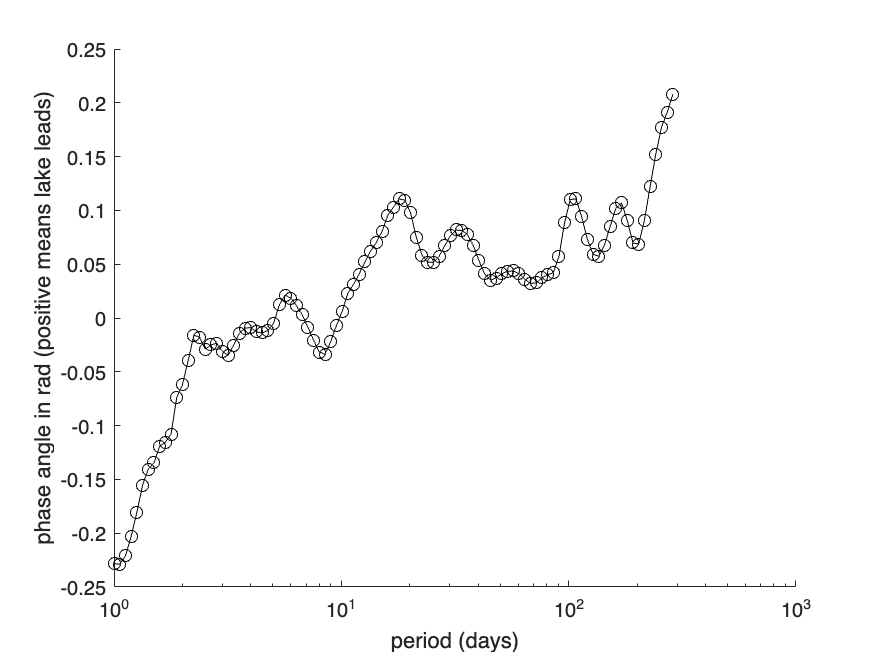

%process the angle explicitly and plot phase angle
Phase = angle(sum(wcsh.*mask,2));

A = Phase;
%unwrap
Phase(A<0) = Phase(A<0)+pi; Phase(A>0) = Phase(A>0)-pi;

figure()

hold on
plot(days(period),Phase,'ko-');
set(gca,'XScale','log')
ylabel('phase angle in rad (positive means lake leads)')
xlabel('period (days)')